### Setup

clear variables 
% Sound driver parameters
Buffersize = 1024;
RecorderChannelMapping = [1 2 3 4 5 6];

% Struct for often used constants
Constants = struct( ...
    'Samplerate', 48000, ...
    'AmountOfMicrophones', length(RecorderChannelMapping), ...
    'UCARadius', 0.40 / 2, ...
    'SpeedOfSound', 343, ...
    'SoundOutputOffset', 0.116 / 2, ... % From Genelec 8010A datasheet (half depth)
    'AlphaOffset', 30, ... % Offset betweeen x-axis and mic 1 in degrees
    'AmountOfTaus', 301, ...
    'AmountOfPhis', 360, ...
    'AmountOfOmegas', 401 ...
    );


% Distance parameters
OffsetMin = (2518 - 0.15 / Constants.SpeedOfSound * Constants.Samplerate) / Constants.Samplerate * Constants.SpeedOfSound;
OffsetMax = (2534 - 0.25 / Constants.SpeedOfSound * Constants.Samplerate) / Constants.Samplerate * Constants.SpeedOfSound;
MinDistance = 0.5;
MaxDistance = 2;

% Execution paths
LiveRecording =false;
Synthesized = true;

Debugging = false;
Continuously = false;

### Loading sound

% Define the sound we want to play
if Synthesized
    load("synthesized_signals.mat")
    ProbeSound = signals.clean;
    Constants.SignalLength = length(ProbeSound);
    Constants.AmountOfMicrophones = 3;
    Constants.AlphaOffset = 60;
    Constants.Samplerate = 24000;
else
    t = 0:1/Constants.Samplerate:0.5;
    ProbeSound = transpose(chirp(t, 50, t(end), 1000, "linear"));

    % Since the sound we wish to play is larger than than buffersize. We need to
    % partition the sound that is going to be played, such that it fits with the
    % buffersize. We choose to pad the sound with silence, such that it fits
    ElementsToAdd = (Buffersize - mod(length(ProbeSound), Buffersize));
    ProbeSound = padarray(ProbeSound, ElementsToAdd, 'post');
    
    % Adding silent frames to the end of the probe sound and scaling it
    SilentFramesToAdd = 24;
    Amplitude = 1.22;
    ProbeSound = padarray(ProbeSound, Buffersize*SilentFramesToAdd, 'post');
    ProbeSound = ProbeSound * Amplitude;
    
    Constants.SignalLength = length(ProbeSound);
    
    % Reshape the sounds to fit with the buffersize
    SoundPartitions = reshape(ProbeSound, Buffersize, []);
end

### Precalculations

PreCalcStart = tic;
% Calculate angular position of microphones
Constants.Betas = UCAangles(Constants.AmountOfMicrophones, Constants.AlphaOffset);

% Define linspaces for Phis, Taus, Omegas
Phis = linspace(0, deg2rad(359), Constants.AmountOfPhis); % In rad
Taus = linspace(MinDistance, MaxDistance, Constants.AmountOfTaus) * 2 / Constants.SpeedOfSound * Constants.Samplerate; % In sample

toc(PreCalcStart)

Elapsed time is 0.008502 seconds.


%clear OmegasBinIndices ProbeFFT 

### Sound driver

if LiveRecording
    SoundDriver = audioPlayerRecorder( ...
        "SampleRate", Constants.Samplerate, ...
        "Device", "ZOOM Audio IF with Rec ASIO", ... % You must choose your own device
        'SupportVariableSize', true, ...
        "BufferSize", Buffersize, ...
        "RecorderChannelMapping", RecorderChannelMapping, ...
        "BitDepth", '32-bit float' ...  
        );
    
    if Debugging
        InputScope = timescope( ...
            'Name', 'Input', ...
            'SampleRate', Constants.Samplerate, ...
            'BufferLength', Buffersize, ...
            'AxesScaling', "auto", ...
            'TimeSpanSource', "property", ... 
            'TimeSpan', 5 ...
            );
        
        OutputScope = timescope( ...
            'Name', 'Output', ...
            'SampleRate', Constants.Samplerate, ...
            'BufferLength', Buffersize, ...
            'AxesScaling', "auto", ...
            'TimeSpanSource', "property", ... 
            'TimeSpan', 5 ...
            );
        
        InputScope.show;
        OutputScope.show;
    end
end

### Echolocation

while true
    EchoStart = tic;
    if Synthesized
        ReceivedSound = signals.reflec;
    elseif LiveRecording
        % Play the sound and store the recorded data into ReceivedSound
        ReceivedSound = PlayAndRecordSound(SoundDriver, SoundPartitions, Constants.AmountOfMicrophones);
        %ReceivedSound = RemoveDelay(ReceivedSound, Constants);
    else
        ReceivedSound = struct2array(load('Recordings\0.6Meter30Degree.mat'));
        ReceivedSound = RemoveDelay(ReceivedSound, Constants);
    end
    
    DelayedSignals = zeros(Constants.SignalLength, Constants.AmountOfMicrophones);
    CostMatrix = zeros(Constants.AmountOfTaus, Constants.AmountOfPhis);
    for TauIdx = 1: Constants.AmountOfTaus
        % TDOA between microphones and ref
        Eta = -Constants.UCARadius * Constants.Samplerate / Constants.SpeedOfSound * cos(Phis(PhiIdx) - Constants.Betas);
        
        for PhiIdx = 1: Constants.AmountOfPhis
            % TOA to microphones
            Delays = round(Taus(TauIdx) + Eta);
            
            for MicIdx = 1: Constants.AmountOfMicrophones
                DelayedSignals(:, MicIdx) = circshift(ReceivedSound(:, MicIdx), -Delays(MicIdx), 1);
            end
            
            DelayedSignals = DelayedSignals .* ProbeSound;
            
            CostMatrix(TauIdx, PhiIdx) = sum(sum(DelayedSignals, 2));
        end
    end
    
    figure
    imagesc(CostMatrix);
    xlabel("DOA");
    ylabel("TOA");
    
    [Distance, Angle] = Estimator(Phis, Taus, CostMatrix, Constants)
    

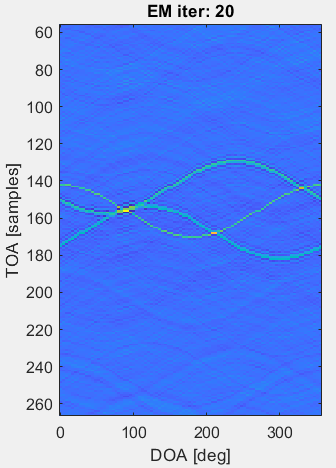 Distance: 1.11, DOA: 90

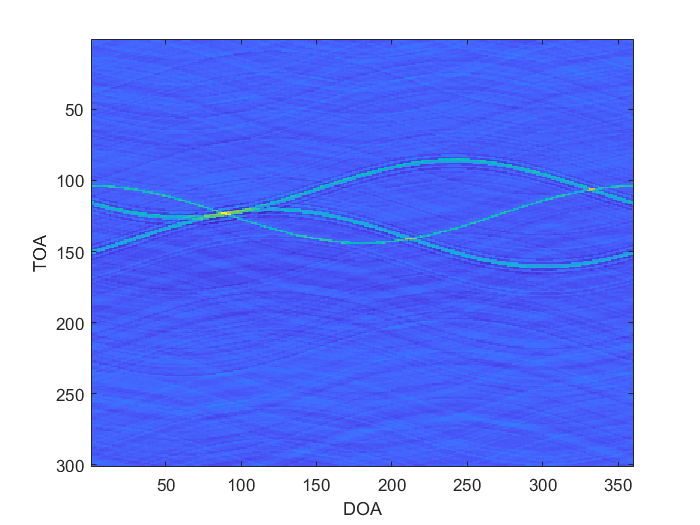

Distance = 1.1100

Angle = 87.5000

Elapsed time is 18.468890 seconds.


    
    toc(EchoStart)
    
    if ~Continuously 
        break;
    end
end

SaveSound = ReceivedSound;